clc
clear all
close all

## input reaction time in mili seconds


y = [607, 583, 521, 494, 369, 782, 570, 678, 467, 620, 425, 395, 346, 361, ...
    310, 300, 382, 294, 315, 323, 421, 339, 398, 328, 335, 291, 329, 310, ...
    294, 321, 286, 349, 279, 268, 293, 310, 259, 241, 243, 272, 247, 275,...
    220, 245, 268, 357, 273, 301, 322, 276, 401, 368, 149, 507, 411, 362,...
    358, 355, 362, 324, 332, 268, 259, 274, 248, 254, 242, 286, 276, 237,...
    259, 251, 239, 247, 260, 237, 206, 242, 361, 267, 245, 331, 357, 284,...
    263, 244, 317, 225, 254, 253, 251, 314, 239, 248, 250, 200, 256, 233,...
    427, 391, 331, 395, 337, 392, 352, 381, 330, 368, 381, 316, 335, 316,...
    302, 375, 361, 330, 351, 186, 221, 278, 244, 218, 126, 269, 238, 194,...
    384, 154, 555, 387, 317, 365, 357, 390, 320, 316, 297, 354, 266, 279,...
    327, 285, 258, 267, 226, 237, 264, 510, 490, 458, 425, 522, 927, 555,...
    550, 516, 548, 560, 545, 633, 496, 498, 223, 222, 309, 244, 207, 258,...
    255, 281, 258, 226, 257, 263, 266, 238, 249, 340, 247, 216, 241, 239,...
    226, 273, 235, 251, 290, 473, 416, 451, 475, 406, 349, 401, 334, 446,...
    401, 252, 266, 210, 228, 250, 265, 236, 289, 244, 327, 274, 223, 327,...
    307, 338, 345, 381, 369, 445, 296, 303, 326, 321, 309, 307, 319, 288,...
    299, 284, 278, 310, 282, 275, 372, 295, 306, 303, 285, 316, 294, 284,...
    324, 264, 278, 369, 254, 306, 237, 439, 287, 285, 261, 299, 311, 265,...
    292, 282, 271, 268, 270, 259, 269, 249, 261, 425, 291, 291, 441, 222,...
    347, 244, 232, 272, 264, 190, 219, 317, 232, 256, 185, 210, 213, 202,...
    226, 250, 238, 252, 233, 221, 220, 287, 267, 264, 273, 304, 294, 236,...
    200, 219, 276, 287, 365, 438, 420, 396, 359, 405, 397, 383, 360, 387,...
    429, 358, 459, 371, 368, 452, 358, 371];


## user indices


ind = [1, 1, 1, 1, 1, 2, 2, 2, 2, 2, 3, 3, 3, 3, 3, 3, 3, 3, 3, 4, 5, 5,...
    5, 5, 5, 5, 5, 5, 5, 5, 5, 5, 5, 5, 5, 5, 6, 6, 6, 6, 6, 6, 6, 6, 6,...
    7, 7, 7, 7, 7, 8, 8, 8, 8, 8, 9, 9, 9, 9, 9, 10, 10, 10, 10, 10, 10,...
    10, 10, 10, 10, 10, 10, 10, 10, 10, 10, 10, 10, 11, 11, 11, 11, 11,...
    11, 11, 11, 11, 11, 11, 11, 11, 11, 11, 11, 11, 11, 11, 11, 12, 12,...
    12, 12, 12, 12, 12, 12, 12, 12, 12, 12, 12, 12, 12, 12, 12, 12, 12,...
    12, 13, 13, 13, 13, 13, 13, 13, 13, 13, 13, 14, 14, 14, 14, 14, 14,...
    14, 14, 14, 14, 14, 14, 14, 15, 15, 15, 15, 15, 15, 16, 16, 16, 16,...
    16, 17, 17, 17, 17, 17, 18, 18, 18, 18, 18, 19, 19, 19, 19, 19, 20,...
    20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20,...
    20, 20, 21, 21, 21, 21, 21, 21, 21, 21, 21, 21, 22, 22, 22, 22, 22,...
    22, 22, 22, 22, 22, 22, 22, 23, 23, 23, 23, 23, 23, 23, 23, 23, 23,...
    24, 24, 24, 24, 24, 24, 24, 24, 24, 24, 24, 24, 24, 24, 24, 24, 24,...
    24, 24, 24, 25, 25, 25, 25, 25, 25, 25, 25, 25, 25, 25, 25, 25, 26,...
    26, 26, 26, 26, 27, 27, 27, 27, 27, 28, 28, 28, 28, 28, 28, 28, 28,...
    28, 29, 29, 29, 29, 29, 29, 29, 29, 29, 29, 30, 30, 30, 30, 30, 30,...
    31, 31, 31, 31, 31, 32, 32, 32, 32, 32, 33, 34, 34, 34, 34, 34, 34,...
    34, 34, 34, 34, 34, 34, 34, 34, 34, 34, 34, 34];

## Getting each theta_j set in logrithmic form

l = 0;
for i =1:max(ind)
    logy{i} = log(y(1+l:l+length(ind(ind==i))));
    l = l+length(ind(ind==i));
end

for i=1:max(ind)
    theta(i) = (mean(logy{i}));
end

## Standardization of data


zlogy = (log(y)-mean(log(y)))/std(log(y));

% ========================================================================

## slice sampling

betaa0 = ones(37,1);
nsamples = 100000;

STDLogSampleRand = slicesample(betaa0,nsamples,'logpdf',@(betaa) ...
    log_post(betaa,zlogy,ind));
                   
LogSampleRand=STDLogSampleRand*std(log(y))+mean(log(y));

MySample=exp(LogSampleRand);
% ========================================================================

## Scatter plot of data

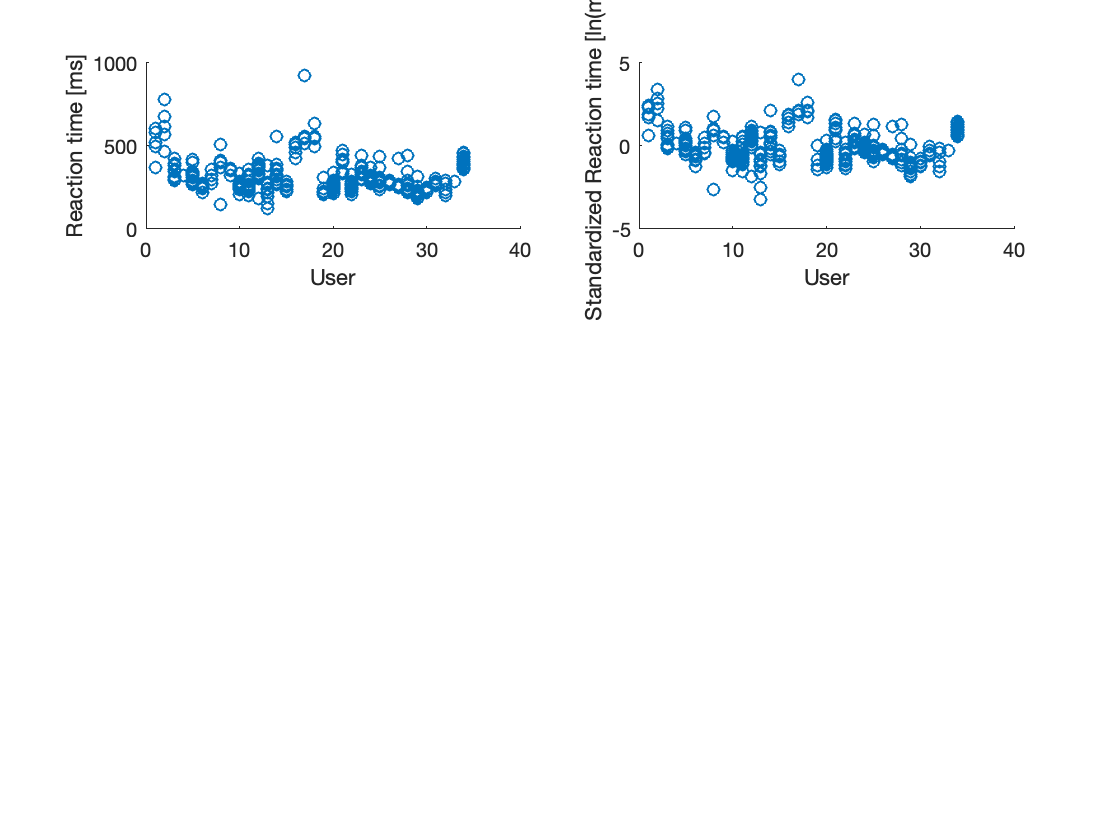

subplot(3,2,1); hold on
scatter(ind,y)
xlabel('User')
ylabel('Reaction time [ms]')
subplot(3,2,2)
scatter(ind,zlogy)
xlabel('User')
ylabel('Standardized Reaction time [ln(ms)]')

% ========================================================================

## Dude's expected reaction time, dude = user no 4

dude_sample=MySample(:,4); figure;hold on; axis('square') histogram(dude_sample,50,'normalization','pdf')

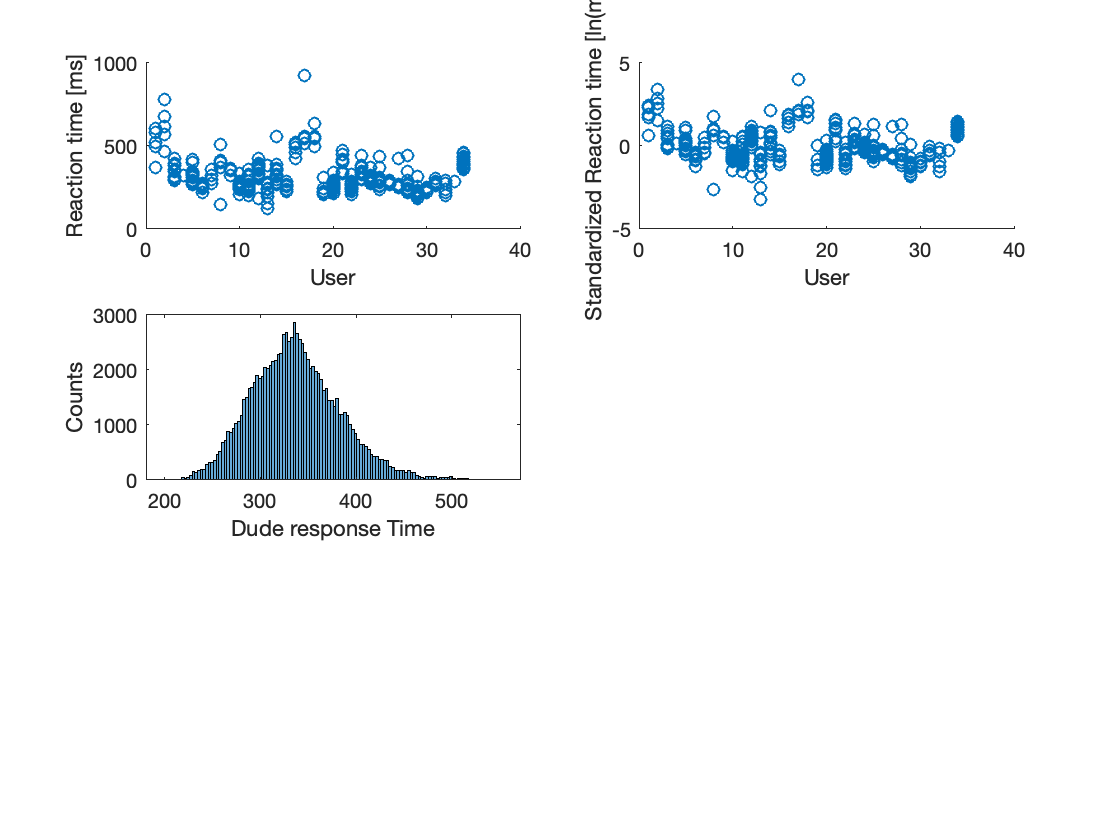

mu2_dude = std(log(y))*STDLogSampleRand(:,4)+mean(log(y));
tau2_dude = std(log(y))*STDLogSampleRand(:,ind(end)+2);

Dude_reacTime = exp(mu2_dude + 0.5* tau2_dude.^2);
subplot(3,2,3)
histogram(Dude_reacTime,128)
xlabel('Dude response Time')
ylabel('Counts')

## Groups expected time

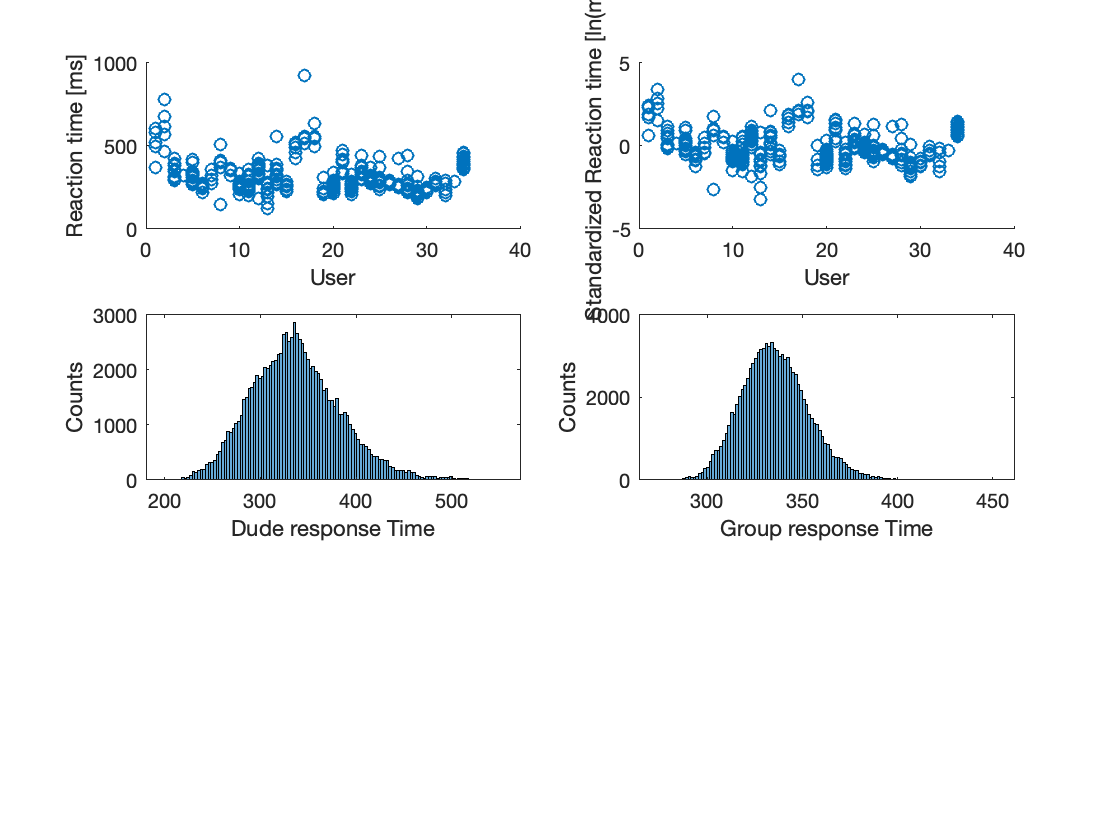

mu2_samp = std(log(y))*STDLogSampleRand(:,ind(end)+1)+mean(log(y));
tau2_samp = std(log(y))*STDLogSampleRand(:,ind(end)+2);
sigma2_samp = std(log(y))*STDLogSampleRand(:,ind(end)+3);
Graoup_reacTime = exp(mu2_samp + 0.5*(sigma2_samp.^2 + tau2_samp.^2));

subplot(3,2,4)
histogram(Graoup_reacTime,128)
xlabel('Group response Time')
ylabel('Counts')

## Random user expected time

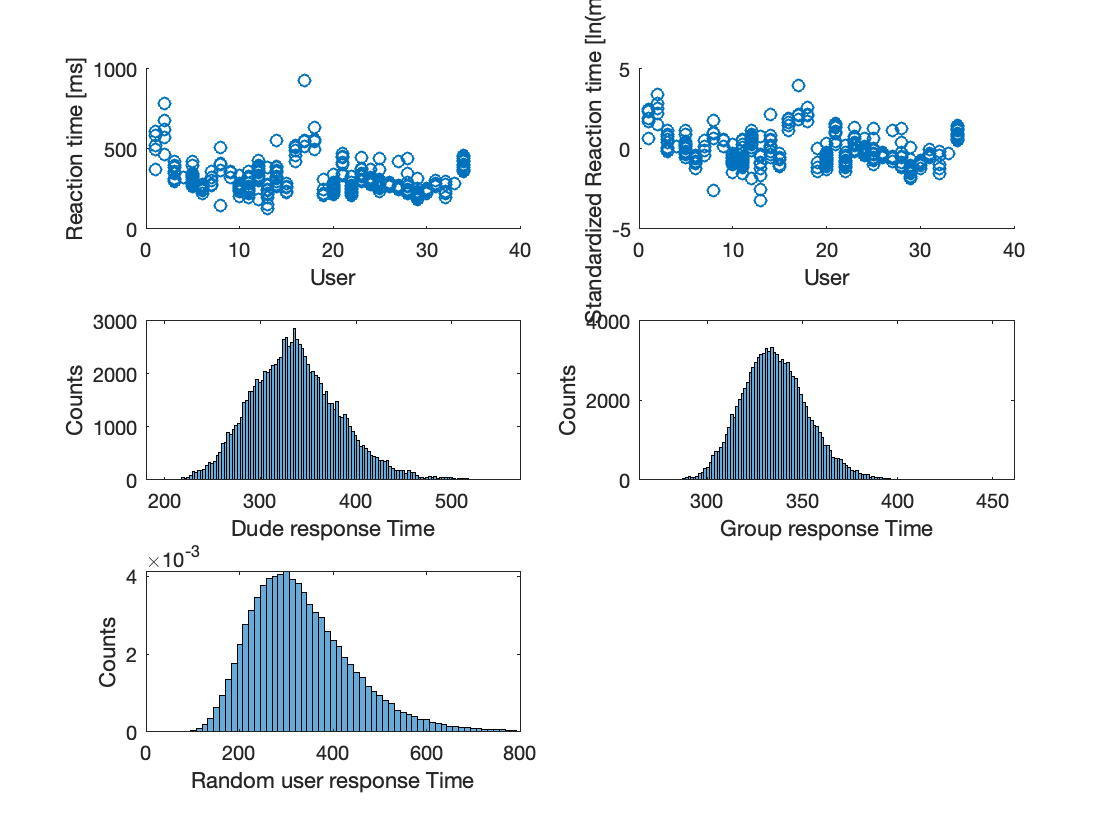

for i = i:size(STDLogSampleRand,1)
    Rand_column(i) = max(round(size(STDLogSampleRand,1)*rand,0),1);
    mu_rand = STDLogSampleRand(Rand_column(i),ind(end)+1);
    tau_rand = STDLogSampleRand(Rand_column(i),ind(end)+2);
    theta_rand(i) = normrnd(mu_rand,tau_rand);
    
    sigma_rand(i) = STDLogSampleRand(Rand_column(i),ind(end)+3);
    logy_picked_rand(i) = normrnd(theta_rand(i),sigma_rand(i));
end
subplot(3,2,5)
rand_user_time = exp(logy_picked_rand*std(log(y))+mean(log(y)));
histogram(rand_user_time,128,'normalization','pdf')
xlabel('Random user response Time')
ylabel('Counts')
xlim([0 800])

## Comparing predicted mean from Bayesian model with that of calculated

## from provided input data

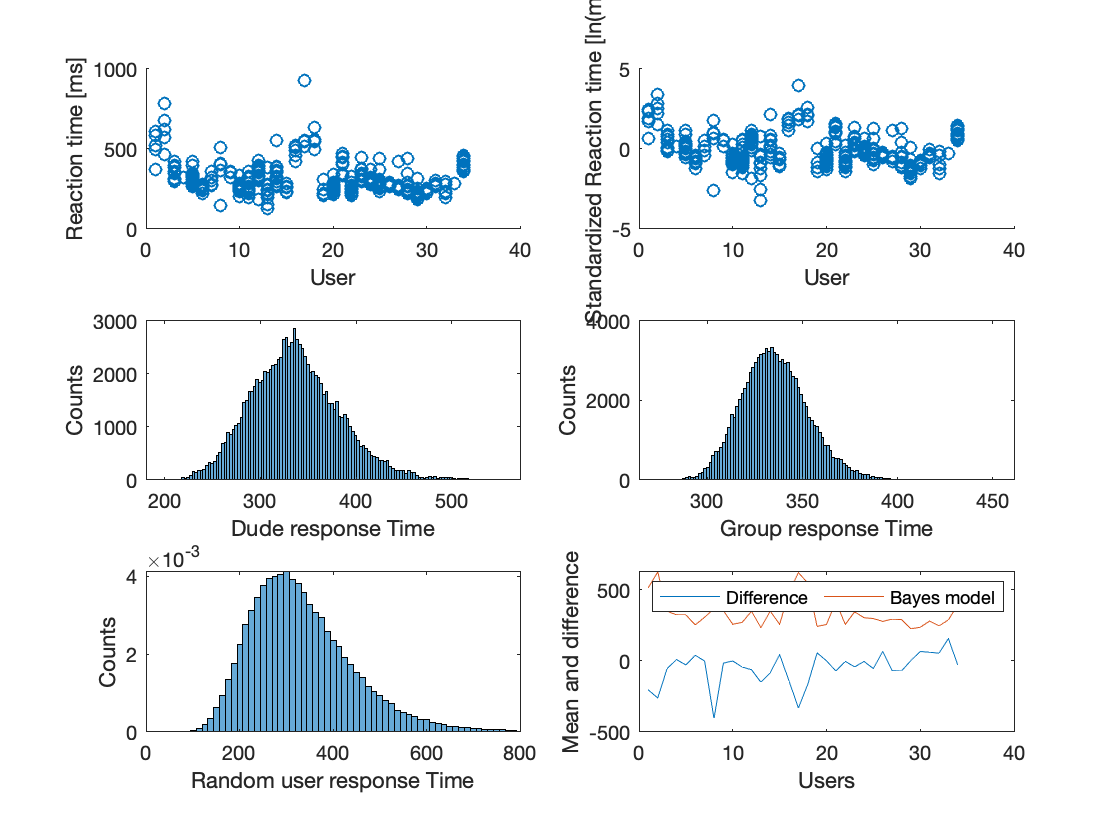

for k = 1:max(ind)
    theta_bayesian(k) = mean(MySample(:,k));
    theta_indiv(k) = mean(exp(logy{k}));
end
subplot(3,2,6)
plot(5000*(theta_bayesian-theta_indiv)./theta_bayesian)
hold on
plot(theta_indiv)
legend({'Difference','Bayes model'},'Location','northwest','Orientation','horizontal')
xlabel('Users')
ylabel('Mean and difference')

%==========================================================================

## Constructing posterior distribution

function lpost=log_post(betaa,zlogy,ind)
theta = betaa(1:end-3);
mu = betaa(end-2);
tau = betaa(end-1);
sigma = betaa(end);

lpost = log_liklihood(betaa,zlogy,ind) + ...
    log_piror_theta(betaa)+log_prior_mu(betaa) + ...
    log_prior_tau(betaa)+log_prior_sigma(betaa);
end

## Setting up prior distributions

function lpmu = log_prior_mu(betaa)  % logrithmic prior for mu
mu = betaa(end-2);
lpmu = 0;
end

function lptau =log_prior_tau(betaa)
tau = betaa(end-1);
if tau >0;lptau = 0;else;lptau = -inf;end
end

function lpsigma = log_prior_sigma(betaa)
sigma = betaa(end);
if sigma >0;lpsigma = 0;else;lpsigma = -inf;end
end

## Construction logrithmic prior for theta

function lpt= log_piror_theta(betaa)
theta = betaa(1:end-3);
mu = betaa(end-2);
tau = betaa(end-1);
sigma = betaa(end);

lpt=0;
for i = 1: length(theta)
    lpt = lpt+(-log(tau)-0.5*((theta(i)-mu)/tau)^2);
end
end

## Constructing liklihood distribution

function ll=log_liklihood(betaa,zlogy,ind)
theta = betaa(1:end-3);
mu = betaa(end-2);
tau = betaa(end-1);
sigma = betaa(end);
theta=theta(:);

ll=0;
for i = 1: length(zlogy)
    ll = ll+(zlogy(i)-theta(ind(i))).^2;
end
ll=-length(zlogy)*log(sigma)-0.5*ll/sigma^2;
end